## Cargar datos

T=readtable('metadata.csv')

T = 1570×3 table
          image           glaucoma    quality
    __________________    ________    _______

    {'image_0001.jpg'}       0           0   
    {'image_0002.jpg'}       0           0   
    {'image_0003.jpg'}       0           0   
    {'image_0004.jpg'}       0           0   
    {'image_0005.jpg'}       1           0   
    {'image_0006.jpg'}       0           0   
    {'image_0007.jpg'}       0           0   
    {'image_0008.jpg'}       0           0   
    {'image_0009.jpg'}       0           4   
    {'image_0010.jpg'}       1           0   
    {'image_0011.jpg'}       0           0   
    {'image_0012.jpg'}       0           0   
    {'image_0013.jpg'}       0           0   
    {'image_0014.jpg'}       0           0   
    {'image_0015.jpg'}       0           0   
    {'image_0016.jpg'}       1           0   


## Preprocesamiento- Separación entrenamiento/validación

T_no_revisada=table(T.image(T.quality==0), T.quality(T.quality==0), T.glaucoma(T.quality==0), 'VariableNames', {'image', 'quality', 'glaucoma'})

T_no_revisada = 1261×3 table
          image           quality    glaucoma
    __________________    _______    ________

    {'image_0001.jpg'}       0          0    
    {'image_0002.jpg'}       0          0    
    {'image_0003.jpg'}       0          0    
    {'image_0004.jpg'}       0          0    
    {'image_0005.jpg'}       0          1    
    {'image_0006.jpg'}       0          0    
    {'image_0007.jpg'}       0          0    
    {'image_0008.jpg'}       0          0    
    {'image_0010.jpg'}       0          1    
    {'image_0011.jpg'}       0          0    
    {'image_0012.jpg'}       0          0    
    {'image_0013.jpg'}       0          0    
    {'image_0014.jpg'}       0          0    
    {'image_0015.jpg'}       0          0    
    {'image_0016.jpg'}       0          1    
    {'image_0017.jpg'}       0          0    


T_revisada=table(T.image(T.quality~=0),T.quality(T.quality~=0) , 'VariableNames', {'image', 'quality'})

T_revisada = 309×2 table
          image           quality
    __________________    _______

    {'image_0009.jpg'}       4   
    {'image_0023.jpg'}       2   
    {'image_0032.jpg'}       4   
    {'image_0038.jpg'}       2   
    {'image_0040.jpg'}       2   
    {'image_0048.jpg'}       4   
    {'image_0065.jpg'}       1   
    {'image_0067.jpg'}       2   
    {'image_0068.jpg'}       3   
    {'image_0069.jpg'}       4   
    {'image_0078.jpg'}       4   
    {'image_0086.jpg'}       4   
    {'image_0094.jpg'}       4   
    {'image_0098.jpg'}       4   
    {'image_0099.jpg'}       1   
    {'image_0100.jpg'}       3   


## Pipeline del procesamiento de calidad

[M N]=size(T_revisada)

M = 309

N = 2

contraste=zeros(M,1);
entropia=zeros(M,1);
MSE=zeros(M,1);
sobel_max=zeros(M,1);
sobel_med=zeros(M,1);
sobel_std=zeros(M,1);
laplace_max=zeros(M,1);
laplace_med=zeros(M,1);
laplace_std=zeros(M,1);
rango_dinamico=zeros(M, 1);
varianza=zeros(M,1); 
min_intensity=zeros(M,1); 
max_intensity=zeros(M,1);
filtro_sobel_y = [-1 0 1; -2 0 2; -1 0 1];
filtro_sobel_x = [-1 -2 -1; 0 0 0; 1 2 1];

 %brisque
for i = 1:M
    I = imread(T_revisada.image{i});
    %if size(img, 3) == 3
    entropia(i) = entropy((I));
    I = double(rgb2gray(I));
   % end
    % Extraer características de imagenes
     
    
    Gx = imfilter(double(I), filtro_sobel_x, 'conv');
    Gy = imfilter(double(I), filtro_sobel_y, 'conv');
    G = Gx + Gy;
    absG = abs(Gx) + abs(Gy);

    Laplaziarra=[0 1 0; 1 -4 1; 0 1 0]; 
    L = imfilter(double(I),Laplaziarra, 'conv'); 
    % 
    % img_filtrada = medfilt2(double(I));
    % MSE(i) = immse(I, img_filtrada);

    % varianza(i) = var(I(:));
   
    contraste(i) = std2(I);  

    min_intensity(i)=min(I(:));
    max_intensity(i)=max(I(:));
    
    % sobel_max(i) = max(abs(absG(:))); 
    % sobel_med(i) = mean(abs(absG(:))); 
    % sobel_std(i) = std(abs(absG(:))); 
    % laplace_max(i)=max(abs(L(:)));
    laplace_med(i)=mean(abs(L(:)));
    % laplace_std(i)=std(abs(L(:)));

end
T_revisada=addvars(T_revisada,contraste, entropia, laplace_med,'NewVariableNames', {'Contraste', 'Entropia','Laplace_media'})

T_revisada = 309×5 table
          image           quality    Contraste    Entropia    Laplace_media
    __________________    _______    _________    ________    _____________

    {'image_0009.jpg'}       4        47.198        7.379         2.8394   
    {'image_0023.jpg'}       2        51.674       7.3154        0.59623   
    {'image_0032.jpg'}       4          48.1       6.5201         1.1611   
    {'image_0038.jpg'}       2        37.792       7.2489        0.42895   
    {'image_0040.jpg'}       2         45.61       6.6841         0.4247   
    {'image_0048.jpg'}       4        52.541       6.9146         1.2941   
    {'image_0065.jpg'}       1        5.7244       4.2585       0.098212   
    {'image_0067.jpg'}       2        43.085        7.008        0.43352   
    {'image_0068.jpg'}       3        76.818

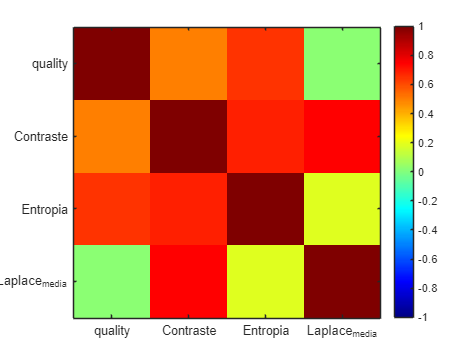

variables = T_revisada.Properties.VariableNames;
writetable(T_revisada,'T_revisadaCaracteristicas.csv')

X = T_revisada{:, 2:end};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:,2:end));
yticks(1:30);
yticklabels(variables(:,2:end));
colormap(jet); colorbar;